# Signal Space and Noise from Unpaired ON DSGC recordings

Looking at signal and noise from cell attached recordings of Superior and Inferior ON DSGCs. These data are not from paired recordings.

downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upMeans = zeros(0, 8);
upSTD = zeros(0, 8);
upStN = zeros(0, 8);
%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass
        continue
    end
    
    [directions, leaf] = sort(loc.Analysis_Results.Orientation);
    
    meanByDirection = cellfun(@mean, loc.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    stdByDirection = cellfun(@std, loc.Analysis_Results.spikesByOrientation(:, 2));
    meanByDirection = meanByDirection(leaf);
    stdByDirection = stdByDirection(leaf);
    StNByDirection = meanByDirection./stdByDirection;
    StNByDirection(isnan(StNByDirection)) = 0;
    StNByDirection(StNByDirection == Inf) = 0;
    
    upMeans(end + 1, :) = meanByDirection';
    upSTD(end + 1, :) = stdByDirection';
    upStN(end + 1, :) = StNByDirection';
end

downMeans = zeros(0, 8);
downSTD = zeros(0, 8);
downStN = zeros(0, 8);
%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass
        continue
    end
    
    [directions, leaf] = sort(loc.Analysis_Results.Orientation);
    
    meanByDirection = cellfun(@mean, loc.Analysis_Results.spikesByOrientation(:, 2));%get the median number of spikes across epochs for each direction
    stdByDirection = cellfun(@std, loc.Analysis_Results.spikesByOrientation(:, 2));
    meanByDirection = meanByDirection(leaf);
    stdByDirection = stdByDirection(leaf);
    StNByDirection = meanByDirection./stdByDirection;
    StNByDirection(isnan(StNByDirection)) = 0;
    StNByDirection(StNByDirection == Inf) = 0;
    
    downMeans(end + 1, :) = meanByDirection';
    downSTD(end + 1, :) = stdByDirection';
    downStN(end + 1, :) = StNByDirection';
end


## Mean Responses and Noise

For every cell, I calculate it's average response and standard deviation for all 8 stimulus directions. From the average response I can plot the average tuning curve across the whole population (note stimulus directions on the x axis are not aligned: 90 deg = preferred direction for inferior cells, 270 = preferred direction for superior cells. Positive directions are counterclockwise).

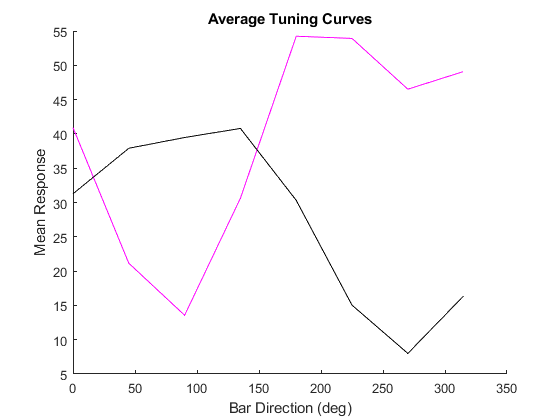

upAvg = mean(upMeans);
downAvg = mean(downMeans);

figure
title('Average Tuning Curves')
hold on
plot([0:45:315], downAvg, 'm')
plot([0:45:315], upAvg, 'k')
xlabel('Bar Direction (deg)')
ylabel('Mean Response')

From the standard deviation of each cell's response I can plot the average noise to all 8 bar directions:

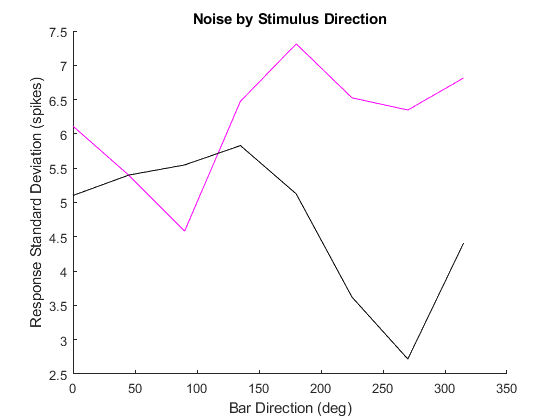

figure
title('Noise by Stimulus Direction')
hold on
plot([0:45:315], mean(downSTD), 'm')
plot([0:45:315], mean(upSTD), 'k')
xlabel('Bar Direction (deg)')
ylabel('Response Standard Deviation (spikes)')

Dividing the average response (first figure) by the noise (second figure) for every cell gives the signal to noise for each stimulus direction. This plot shows the average signal to noise across populations:

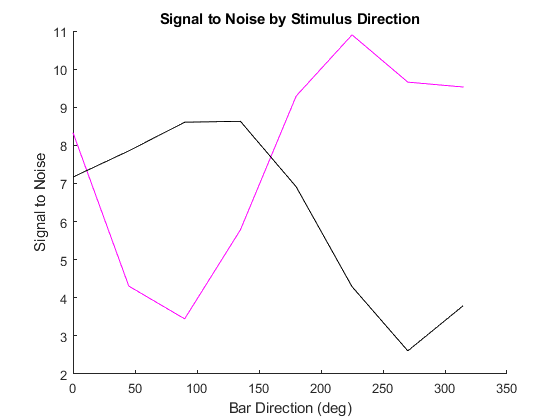

figure
title('Signal to Noise by Stimulus Direction')
hold on
plot([0:45:315], mean(downStN), 'm')
plot([0:45:315], mean(upStN), 'k')
xlabel('Bar Direction (deg)')
ylabel('Signal to Noise')

Tuning curves can also be viewed in the signal space. Here is the signal space given the average responses shown in the first figure.

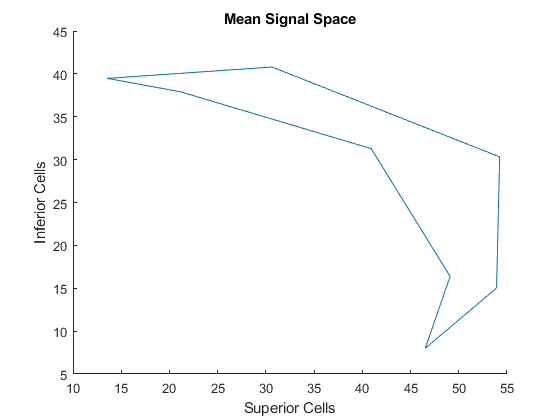

figure
title('Mean Signal Space')
hold on
plot([downAvg, downAvg(1)], [upAvg, upAvg(1)])
xlabel('Superior Cells')
ylabel('Inferior Cells')

I can then plot the noise (from the second figure) as error bars on the average response shown in signal space. Because we haven't done paired recordings, this plot does not tell us about whether there are correlations or if noise points in a certain direction. It only gives the magnitude of noise for each cell type. Still, it might be somewhat meaningful as it sort of places an upper and lower bound on the possible effects of noise on decoding (encoding?). Again, the noise here is a standard deviation, so visually it under estimates the full width of the distributions.

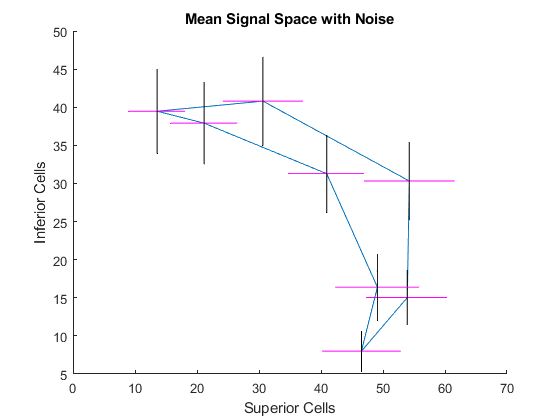

figure
title('Mean Signal Space with Noise')
hold on
plot([downAvg, downAvg(1)], [upAvg, upAvg(1)])
xlabel('Superior Cells')
ylabel('Inferior Cells')
for i = 1:8
    point = [downAvg(i), upAvg(i)];
    downNoise = mean(downSTD(:, i)); %2 times the mean standard standard deviation of responses for this stimulus direction
    upNoise = mean(upSTD(:, i));    
    plot(point(1) + [-downNoise, downNoise], [point(2), point(2)], 'm')
    plot([point(1), point(1)], point(2) + [-upNoise, upNoise], 'k')
end

## Response Magnitude Versus Noise

Finally, I plotted the magnitude of responses against the magnitude of noise and the signal to noise. It looks like there is a positive correlation between these metrics. I think this was also observed in salamander OFF DSGCs.

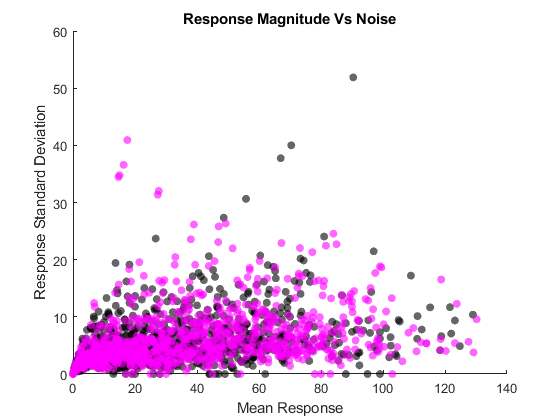

allDownMeanResponses = downMeans(:);
allDownNoise = downSTD(:);
allUpMeanResponses = upMeans(:);
allUpNoise = upSTD(:);

figure
title('Response Magnitude Vs Noise')
hold on
scatter(allUpMeanResponses, allUpNoise, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(allDownMeanResponses, allDownNoise, 'm', 'filled', 'MarkerFaceAlpha', 0.6);
xlabel('Mean Response')
ylabel('Response Standard Deviation')

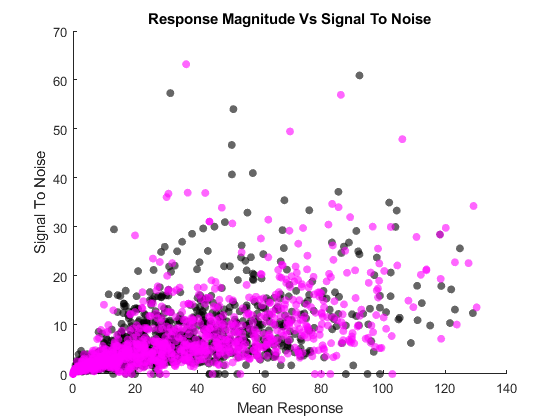

allDownStN = downStN(:);
allUpStN = upStN(:);

figure
title('Response Magnitude Vs Signal To Noise')
hold on
scatter(allUpMeanResponses, allUpStN, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(allDownMeanResponses, allDownStN, 'm', 'filled', 'MarkerFaceAlpha', 0.6);
xlabel('Mean Response')
ylabel('Signal To Noise')

The relationship between noise and signal to noise is strange, but clearly contains a lot of structure

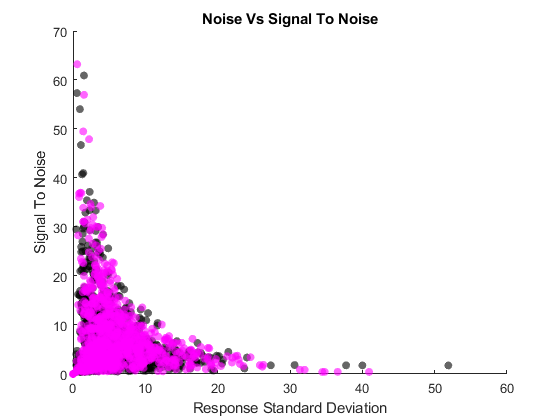

figure
title('Noise Vs Signal To Noise')
hold on
scatter(allUpNoise, allUpStN, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
scatter(allDownNoise, allDownStN, 'm', 'filled', 'MarkerFaceAlpha', 0.6);
xlabel('Response Standard Deviation')
ylabel('Signal To Noise')